% Step-down switch converter
% Vin =  6V - 8.4V
% Vout = 3.3V 2-3A
% Fs= 500kHz
% Minimum load current (for CCM) = 250mA (was 100mA)
% Maximum Load Current = 3A

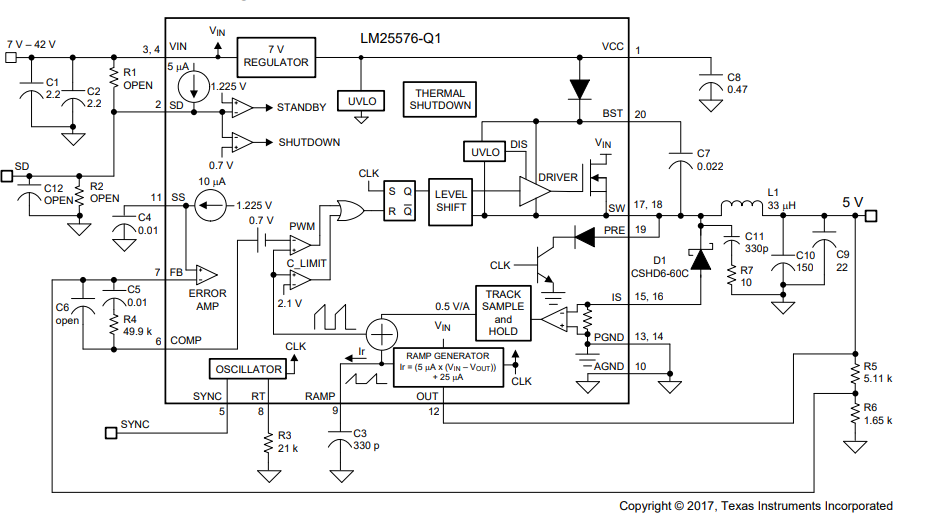

% Calculation of RT

% 580e-9 and 135e-12 are constants from internal oscillator timing
% characteristics

RT=((1/(500e3))- 580e-9)/(135e-12)

RT = 1.0519e+04

% answer is 10.5k, nearest e24 = 10k (5%), e96 = 10.5k (1%)

Fswe24 = 1/(580e-9+(135e-12)*10.51e3) % im buying e24 smd resistors, 

Fswe24 = 5.0029e+05

% adafruit 441 book has 10k + 510 =10.51 ------ do this ------


Fswe96 = 1/(580e-9+(135e-12)*10.5e3) 

Fswe96 = 5.0063e+05


% picture example below


% this section is for calculating the inductor value

% inductor ripple must be smaller than 2*iout,min
twoXiout= 2*0.100

twoXiout = 0.2000

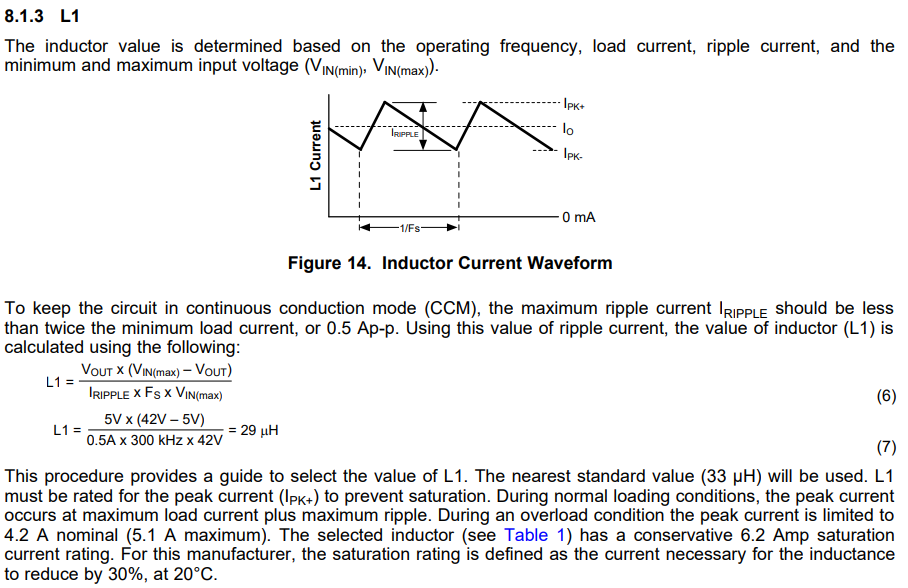

% minimum load current is 100mA
% 9V for headroom on Vin
L = ((3.3)*(9-3.3))/(0.5*500e3*9)

L = 8.3600e-06


%8.36uH inductor, closest is 4.2uH i think

% milli -micro- nano -pico

% https://dk.rs-online.com/web/p/smd-spoler/2317197

% the inductor above has Irms=5A, Isat=7.5A, metal allow construction 
% DCR = 64mOhm  P = I^2rms * DCR
P=3^2*64e-3 % (same but add good copper around inductor for heat dissipation)

P = 0.5760


% SRF = 12MHz well above 500kHz (self resonant frequency) 
% (rule of thumb SRF atleast 10x higher than Fs (it is)
% Fs *10 is 5Mhz
% Shielded metal-alloy core: good for low noise at 500 kHz.


% ramp capacitor With the inductor value selected,
% the value of C3 (CRAMP) necessary for the emulation ramp circuit is:
% use nominal inductor value (the theoretical closest real value)
% (suggested by TX)

Cramp = 8.2e-6*10^-5

Cramp = 8.2000e-11


% so 82 pF ceramic capictor

% E12 series is 82 Pico Farad (choice) (in adafruit 441 book)



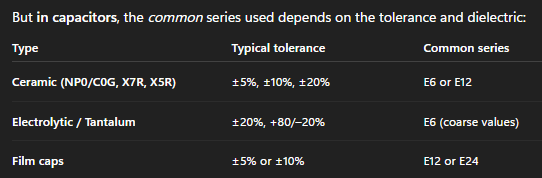

% Calculation of output capacitors



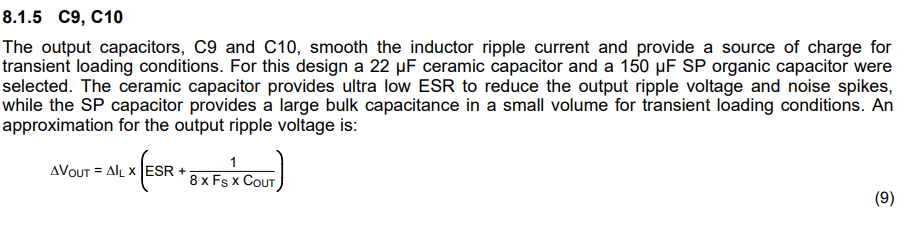

Delta_IL_max = (3.3*(1-(3.3/8.4)))/(8.2e-6*500e3)

Delta_IL_max = 0.4887


Delta_IL_min = (3.3*(1-(3.3/6)))/(8.2e-6*500e3)

Delta_IL_min = 0.3622

% ESR =  equivilant series resistance


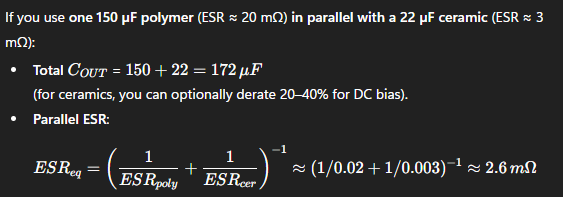

ESReq=(1/0.02+1/0.003)^-1

ESReq = 0.0026


% polymer + ceramic gives you very low ripple

% use 1 polymer as bulk cap with low esr and use a ceramic for 
% polymer bulk cap https://de.farnell.com/en-DE/panasonic/eefsx0j151er/cap-150uf-6-3vdc-alu-elec-poly/dp/1751929
% ceramic cap 

%DeltaVout = 





% calculating R5, R6



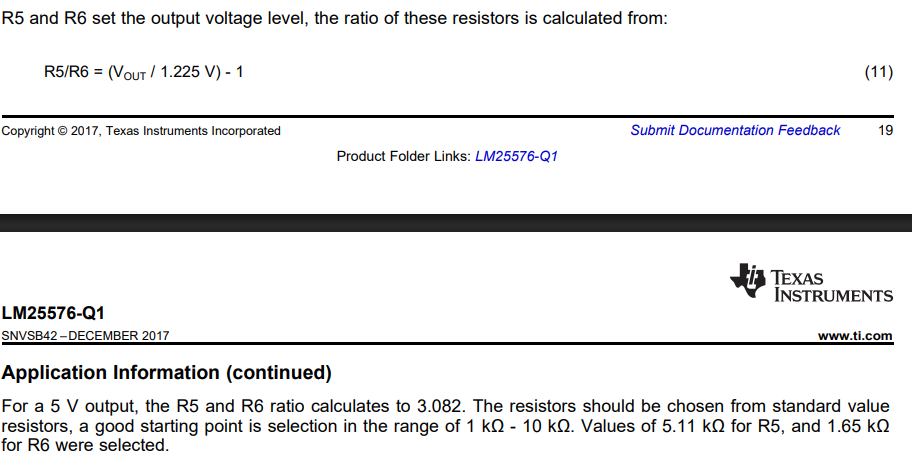

rfive_div_rsix = (3.3/1.225)-1

rfive_div_rsix = 1.6939

% for 3.3V = 1.6939
rfive = ((3.3/1.225)-1)*3.3e3

rfive = 5.5898e+03


% r5 = 5.1k, r6=3.3k (in adafruit 441)


% calculating R1 R6 C12 (see initial schematic in datasheet)